## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15), 'm', 1.0, 'Ic', 0.5^2 / 12);
mbs = add_body(mbs, "slider", -0.6, 'm', 3.0, 'Ic', 0.1)

mbs = struct with fields:
     bodies: [1×3 struct]
     joints: [1×1 struct]
         nq: 9
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


Get mass matrix

M = mass_matrix(mbs);

### Forces definition

mbs = add_gravity(mbs, [0, -9.81]);

### Force vector

q0 = initial_position(mbs);
F = forces(mbs, q0);

Simple checking for the gravity forces

qpp = M\F;

### Solve system using ode45

Define all the inputs to the system

qd0 = zeros(size(q0)); % initial velocity
qd0([1, 5]) = -0.1; % Set vx of crank and vy of link
accfun = @(t, y)acceleration(mbs, q0, qd0, t);
[t, y] = ode45(accfun, [0,1], qd0);
Y = cumtrapz(t,y);

Make some plots to check the results

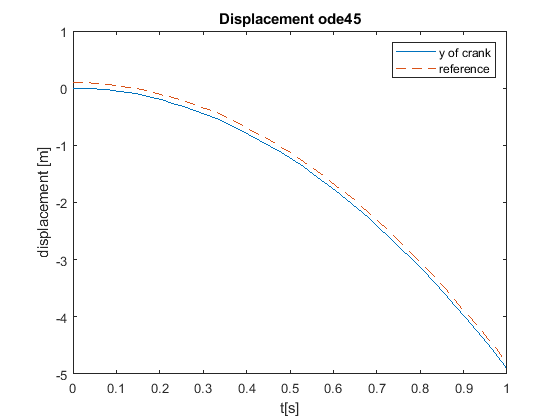

plot(t, Y(:, 2), t, q0(2) + t.*qd0(2) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of crank', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')
title('Displacement ode45')

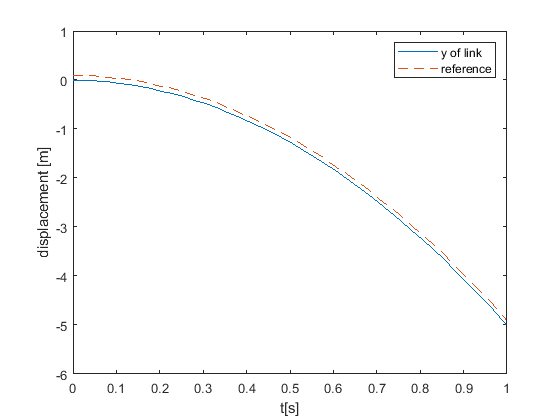

plot(t, Y(:, 5), t, q0(5) + t.*qd0(5) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

## System two - single body with simple constraint under gravity

mbs = init_mbs();
mbs = add_body(mbs, "block", 0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_simple_joint(mbs, "blockx", "block", "x", 0.1);
mbs = add_gravity(mbs, [7.12, 12.9]);

q0 = initial_position(mbs);
qd0 = zeros(size(q0));

accfun = @(t, y)acceleration(mbs, qd0, q0, t);
[t, y] = ode45(accfun, [0,1], qd0);
z = cumtrapz(t,y);


Plot and check

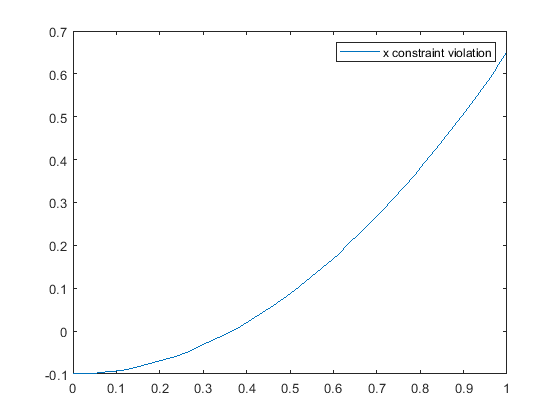

plot(t, z(:, 1) - q0(1))
legend('x constraint violation')

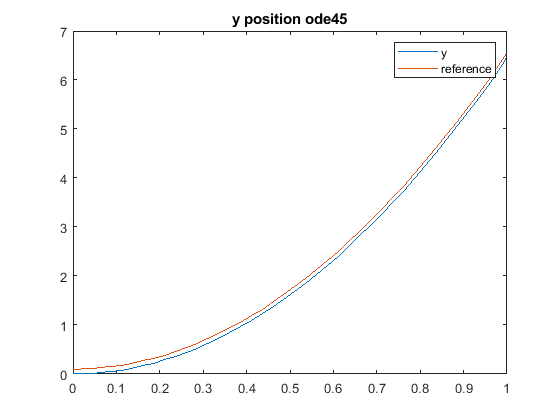

plot(t, z(:, 2), t, q0(2) + 0.5 * 12.9 .* t.^2)
legend('y', 'reference')
title('y position ode45')

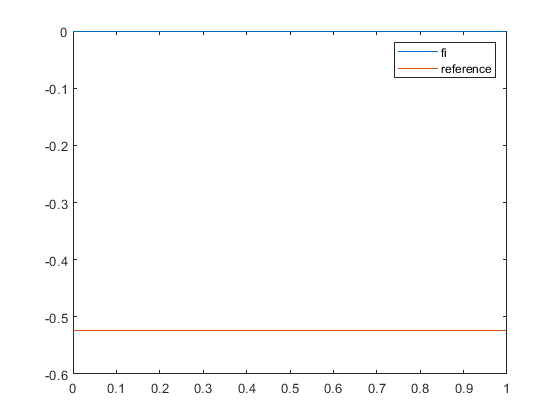

plot(t, z(:, 3), t, q0(3) * ones(size(t)))
legend('fi', 'reference')